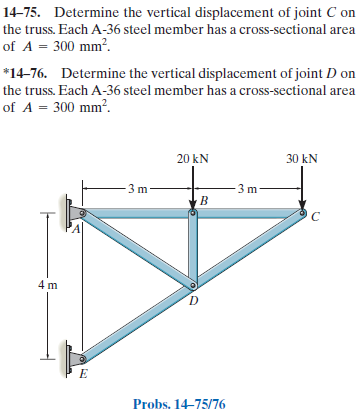

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-75P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-75P-solution-9780136022305) (problem 14-75)

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-76P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-76P-solution-9780136022305) (problem 14-76)

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# joint data

theta = atand(sym(4/6))*u.deg;
jointA = [0 0]*u.m;
jointB = [3 0]*u.m;
jointC = [6 0]*u.m;
jointD = [3 -2]*u.m;
jointE = [0 -4]*u.m;

# member data

E = 200*u.GPa;
A = 300*u.mm^2;

# truss

t = Truss;
t = t.add('reaction', 'Ra', {'Rax' 'Ray'}, jointA);
t = t.add('reaction', 'Re', {'Rex' 'Rey'}, jointE);
t = t.add('concentrated', 'Pb', [0 -20]*u.kN, jointB);
t = t.add('concentrated', 'Pc', [0 -30]*u.kN, jointC);
t = t.add('joint', 'A', jointA);
t = t.add('joint', 'B', jointB);
t = t.add('joint', 'C', jointC);
t = t.add('joint', 'D', jointD);
t = t.add('joint', 'E', jointE);
t = t.add('member', 'Fab', jointA, jointB, E, A);
t = t.add('member', 'Fbc', jointB, jointC, E, A);
t = t.add('member', 'Fcd', jointC, jointD, E, A);
t = t.add('member', 'Fde', jointD, jointE, E, A);
t = t.add('member', 'Fad', jointA, jointD, E, A);
t = t.add('member', 'Fbd', jointB, jointD, E, A);

# solution

[us ua ms ma ls la] = t.solve('Mode', 'factor');

# joint displacements

ua_vpa = vpa(ua, 4) %#ok<NASGU> 

$$ua\_vpa = \left(\begin{array}{cc} \mathrm{uA} & 0\\ \mathrm{vA} & 0\\ \mathrm{uB} & 2.25\,\mathrm{mm}\\ \mathrm{vB} & -5.549\,\mathrm{mm}\\ \mathrm{uC} & 4.5\,\mathrm{mm}\\ \mathrm{vC} & -20.42\,\mathrm{mm}\\ \mathrm{uD} & -1.953\,\mathrm{mm}\\ \mathrm{vD} & -4.883\,\mathrm{mm}\\ \mathrm{uE} & 0\\ \mathrm{vE} & 0 \end{array}\right)$$

# forces on the truss

ma_f_m_vpa = vpa(ma.f.m, 4) %#ok<NASGU> 

$$ma\_f\_m\_vpa = \left(\begin{array}{cc} \mathrm{Fab} & 45.0\,\mathrm{kN}\\ \mathrm{Fbc} & 45.0\,\mathrm{kN}\\ \mathrm{Fcd} & -54.08\,\mathrm{kN}\\ \mathrm{Fde} & -72.11\,\mathrm{kN}\\ \mathrm{Fad} & 18.03\,\mathrm{kN}\\ \mathrm{Fbd} & -20.0\,\mathrm{kN} \end{array}\right)$$

la_f_c = la.f.c %#ok<NASGU> 

$$la\_f\_c = \left(\begin{array}{cccc} \mathrm{Ra} & -60\,\mathrm{kN} & 10\,\mathrm{kN} & 0\\ \text{Re} & 60\,\mathrm{kN} & 40\,\mathrm{kN} & 0\\ \mathrm{Pb} & 0 & -20\,\mathrm{kN} & 0\\ \mathrm{Pc} & 0 & -30\,\mathrm{kN} & 0 \end{array}\right)$$

ma_f_c = ma.f.c %#ok<NASGU> 

$$ma\_f\_c = \left(\begin{array}{cccc} \mathrm{Fab} & 45\,\mathrm{kN} & 0 & 0\\ \mathrm{Fbc} & 45\,\mathrm{kN} & 0 & 0\\ \mathrm{Fcd} & 45\,\mathrm{kN} & 30\,\mathrm{kN} & 0\\ \mathrm{Fde} & 60\,\mathrm{kN} & 40\,\mathrm{kN} & 0\\ \mathrm{Fad} & 15\,\mathrm{kN} & -10\,\mathrm{kN} & 0\\ \mathrm{Fbd} & 0 & 20\,\mathrm{kN} & 0 \end{array}\right)$$

la_f_m_vpa = vpa(la.f.m, 4) %#ok<NASGU> 

$$la\_f\_m\_vpa = \left(\begin{array}{cc} \mathrm{Ra} & 60.83\,\mathrm{kN}\\ \text{Re} & 72.11\,\mathrm{kN}\\ \mathrm{Pb} & 20.0\,\mathrm{kN}\\ \mathrm{Pc} & 30.0\,\mathrm{kN} \end{array}\right)$$

# moments on the truss

ma_m_m = ma.m.m %#ok<NASGU> 

$$ma\_m\_m = \left(\begin{array}{cc} \mathrm{Fab} & 0\\ \mathrm{Fbc} & 0\\ \mathrm{Fcd} & 180\,\mathrm{kN}\,m\\ \mathrm{Fde} & 240\,\mathrm{kN}\,m\\ \mathrm{Fad} & 0\\ \mathrm{Fbd} & 60\,\mathrm{kN}\,m \end{array}\right)$$

la_m_c = la.m.c %#ok<NASGU> 

$$la\_m\_c = \left(\begin{array}{cccc} \mathrm{Ra} & 0 & 0 & 0\\ \text{Re} & 0 & 0 & 240\,\mathrm{kN}\,m\\ \mathrm{Pb} & 0 & 0 & -60\,\mathrm{kN}\,m\\ \mathrm{Pc} & 0 & 0 & -180\,\mathrm{kN}\,m \end{array}\right)$$

ma_m_c = ma.m.c %#ok<NASGU> 

$$ma\_m\_c = \left(\begin{array}{cccc} \mathrm{Fab} & 0 & 0 & 0\\ \mathrm{Fbc} & 0 & 0 & 0\\ \mathrm{Fcd} & 0 & 0 & 180\,\mathrm{kN}\,m\\ \mathrm{Fde} & 0 & 0 & 240\,\mathrm{kN}\,m\\ \mathrm{Fad} & 0 & 0 & 0\\ \mathrm{Fbd} & 0 & 0 & 60\,\mathrm{kN}\,m \end{array}\right)$$

la_m_m = la.m.m %#ok<NASGU> 

$$la\_m\_m = \left(\begin{array}{cc} \mathrm{Ra} & 0\\ \text{Re} & 240\,\mathrm{kN}\,m\\ \mathrm{Pb} & 60\,\mathrm{kN}\,m\\ \mathrm{Pc} & 180\,\mathrm{kN}\,m \end{array}\right)$$

# clean up

assume(old_assum);
clear old_assum;
clear ua_vpa;
clear ma_f_m_vpa la_f_c ma_f_c la_f_m_vpa;
clear ma_m_m la_m_c ma_m_c la_m_m;